# Case 1: Brain self-regulation toy example

## This is the simplest Active Inference case of brain self-regulation learning:  A one-layer that act and infere and learn into a 1 hidden states factor with uncertainty in the 'baseline' observation. The learning is over the prior transition mappings. 

#### Here we design the 'thermometer' mapping between brain states and thermometer observations. 

#### The layer is characterized by having a total of 4 states. The mapping of 2 states corresponds to 'Up' and 'Down observations. However, the mapping between the other two states corresponds to a noisy baseline observation; also, the transition between those states are random. 

This case can be addapted to represent: 

(WRITE IF CONDITIONALS)

More hidden states

Learning A, B, and A-B

close all
clear all
cd

C:\Users\gadri\spm12\toolbox\DEM\GVG_and_tutorial_pomdp\Supplementary code\GVG_DEM\hierarchical



rng('shuffle'); 

#### Hyperparameters to play with

pr1     =   0.1; % a - precision (inverse termperature) parameter (lower = less precise)
conf1   =   0.1; % D-map -  modify the level of confidence in the beliefs: {up, down, left, right}

%%%% C-map - Parameters that represent avoidance and preference observations 
avoid = - 0.9; 
prefr = 10; 

%%%% Learning Rate
eta = 0.6; 

#### Time   

T_1 =  2;   % Times steps in a trial
total_trainig = 10; % Numbers of trials
time = (['t' num2str(T_1) 'x' num2str(total_trainig) ]);

#### Numbers of states, observations  and actions

Here we have 1 hidden state factor: The dimentions of the SMA 

and we have 1 outcome factor : The observed location in the thermometer 

and we have 1 action factor: The actions over the 1st level

ns1 = 4; %number of state 1st factor: location {up, down, left, right}
no1 = 3; % number of observations 1st factor: thermometer {up, down, baseline}
action1 = 4; % number of action 1st factor: {up, down, let, right}

## We start building the POMDP

#### Prior beliefs about initial states

D{1} = zeros(ns1 , 1); %  location {up, down, left, right}

Number of states in each state factor

Ns =  [length(D{1})];  ;%number of states per modality

#### Probabilistic (likelihood) mapping from hidden states to outcomes - A map

The rows are the outcomes, and the columns are the alternative levels of the first hidden state factor.

A{1} = zeros(no1 , Ns(1) ); % Observations x States of 1st factor

Here we define the value per states according to the total number of states

flat1 = 1 / ns1; % Flat probability Observation 1: between states when are observed as baseline
certainstate = 1-flat1;
unceratinstate = ((flat1*ns1)- (2*flat1));

Here we define the likelihood matrix, with high certainty oof states when ti is observed the  'up' and 'down' observation, but uncertainti when it is observe a baseline

% States:      up  down left right | Observations:
A{1}(:,:,1) = [ certainstate    0      0   0;     % Up

                0       certainstate   0   0 ;    % Down

               flat1    flat1   unceratinstate   unceratinstate ];   % Baseline


#### Transition between states -  B map

The rows are the states in current time $s_{t+1}$ , columns are the states in the previous time $s_{t}$, and the 3d position are the allowable actions.

Here we have the total possible transitions between all the states

B{1}= zeros(Ns(1), Ns(1), action1); 

for i = 1:Ns(1)
    B{1}(i,:,i) = 1; 
end

#### Learning the transition - b learning

b   =      B;

for i = 1:Ns(1)
 b{1}(:,:,i) = rand(action1); 
end

b{1} = spm_softmax( pr1 * log( b{1} + exp(-4) )); % noise with pr1


#### Prior preferences over the outcomes - C map

Columns correspond to different time steps.

Here we have the preferences of observe 'Up', a strong avoidance to  observe 'Down', and avoidance to observe 'Baseline'

C{1} = zeros(no1, T_1);
C{1}(1,:) = prefr;  % Up 
C{1}(2,:) = avoid; % Down
C{1}(3,:) = 0; %Baselines

#### Policies

The rows are the alternative policies 

the columns are the hidden states factors, 

Here we have 1 policy that comprehen the 4 possible transitions

Np = action1; % Number of policies
Nf = 1; % Number of state factors
U         = zeros(1,Np,Nf);

U(:,:,1) = [1 2 3 4]; % 

### POMDP structure

mdp_1.T = T_1;                    % number of updates / time steps
mdp_1.A = A;                      % likelihood mapping
mdp_1.B = B;                      % prior transition probabilities
mdp_1.D = D;                      % prior over initial states
mdp_1.C = C;                      % prior preferred states
mdp_1.U = U;                      % action/policies
% Hyperparameters
mdp_1.erp = 1;                  % degree of belief resetting at each timestep 
                                % or reset the posterior over states. default=1, no decay

% learning:
mdp_1.eta = eta;                 % learning rate
mdp_1.b = b;



#### Labels

label.factor{1}   = 'Location ';   
label.name{1}    = {'1', '2', '3', '4'};
label.modality{1} = 'Thermometer ';  
label.outcome{1} = {'Up', 'Down', 'Flat'};

mdp_1.Aname{1} = {'Stimulus'};
mdp_1.Bname{1} = {'States'};

mdp_1.label = label;

### CHECK

MDP_1 = spm_MDP_check(mdp_1);

### Solver

MDP = spm_MDP_VB_X_tutorial(MDP_1); 

#### PLOTS

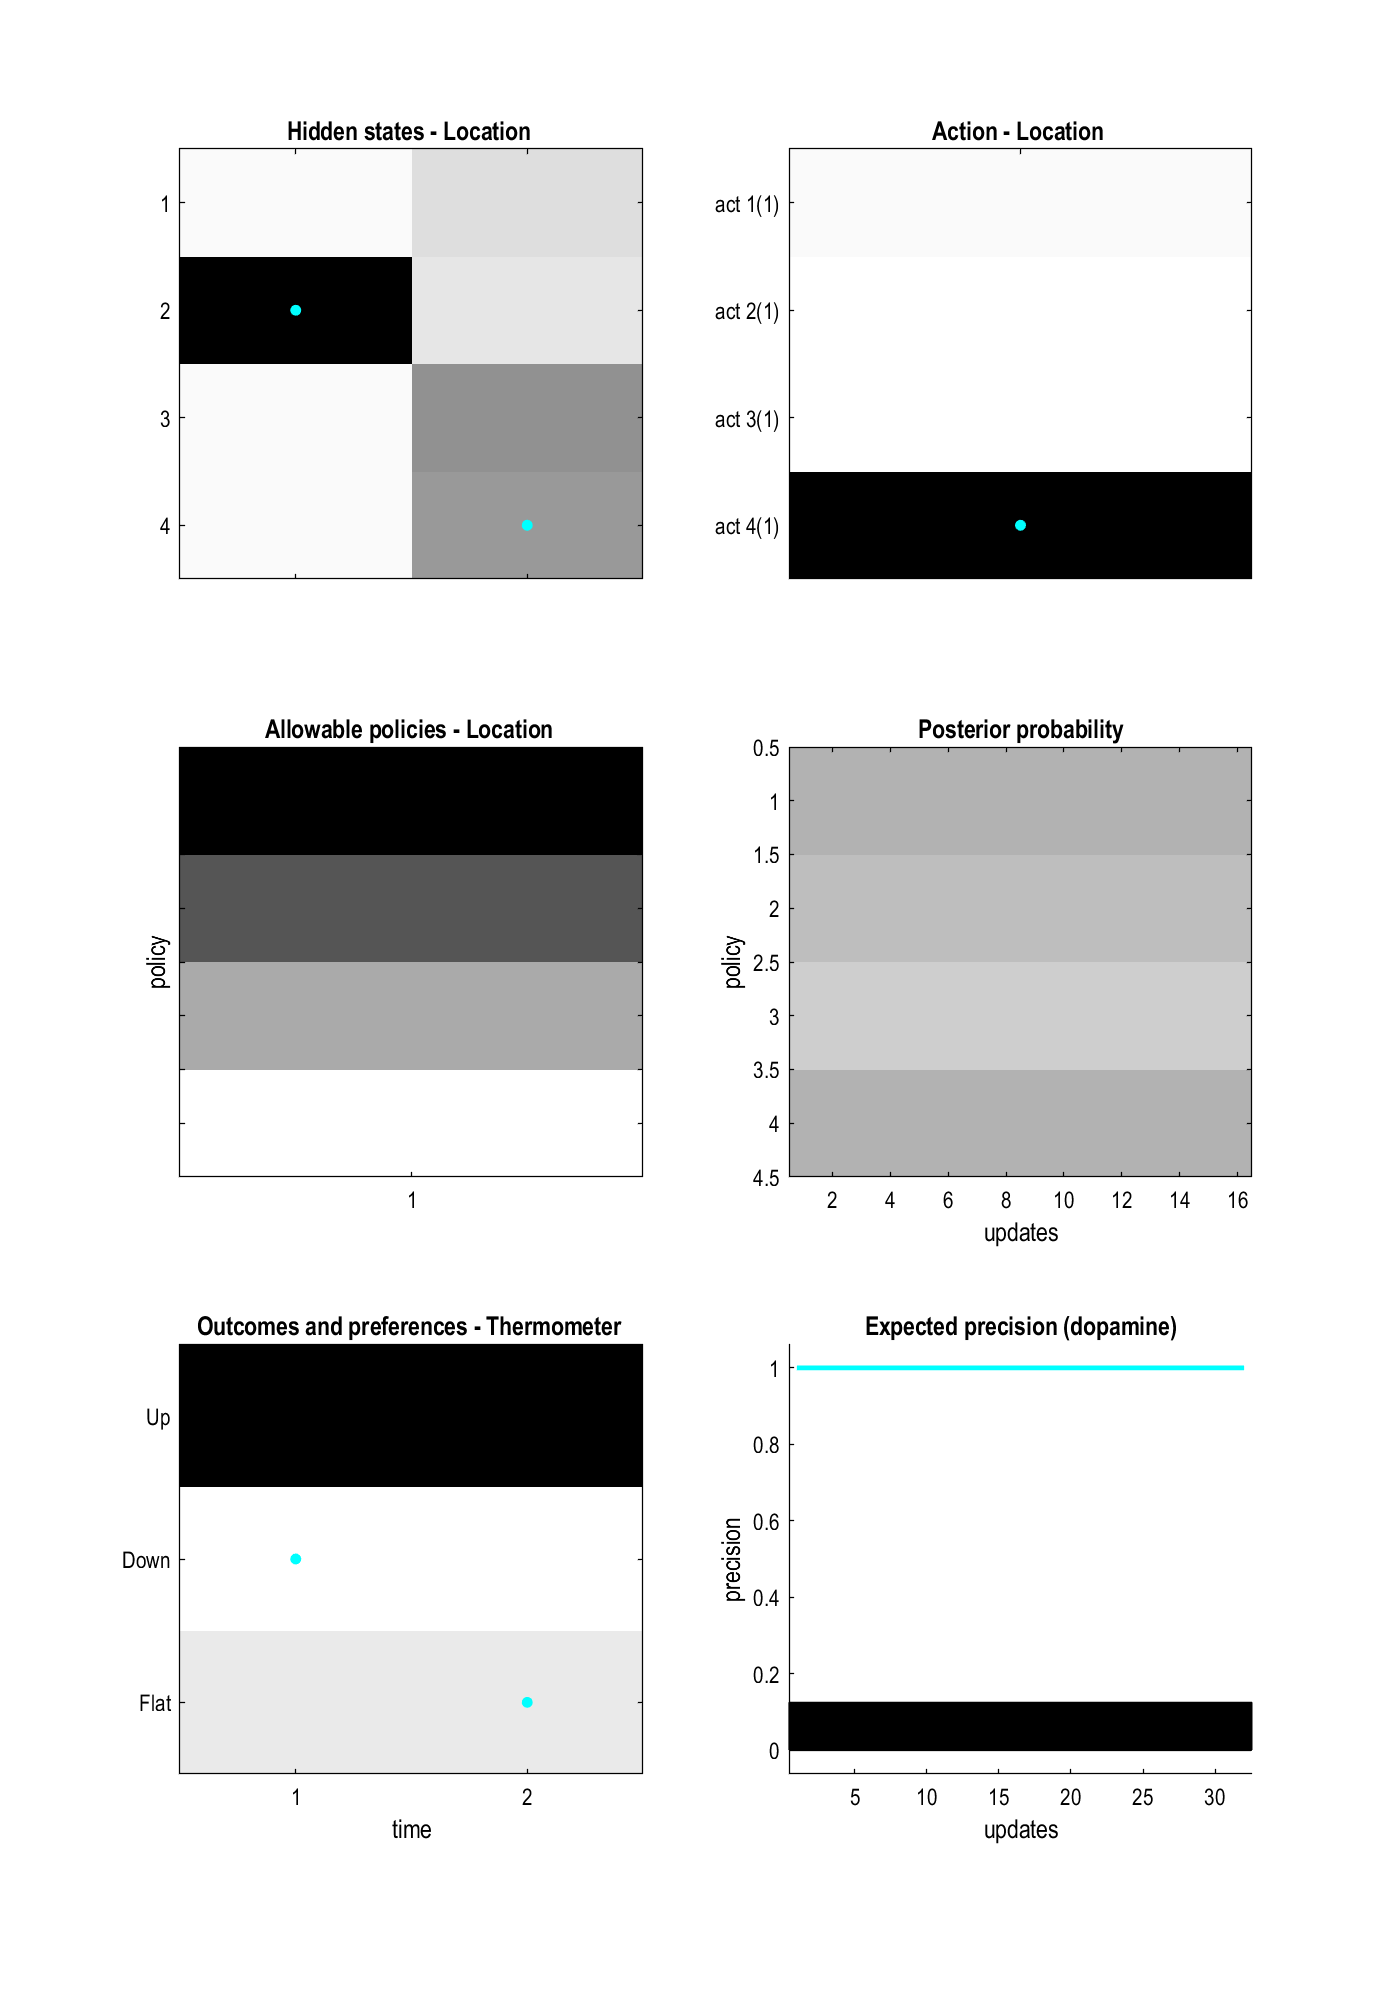

spm_figure('GetWin','Figure 1'); clf    % display behavior
spm_MDP_VB_trial(MDP); 

#### Let's check during more trials . . . 

MDP = spm_MDP_VB_X_tutorial(MDP_1); % Recall POMDP structure
N = total_trainig; % add number of trials
MDP = mdp_1; % use structure
[MDP(1:N)] = deal(MDP); 
MDP = spm_MDP_VB_X_tutorial(MDP); % Solver


#### ... with better plots

### Inference

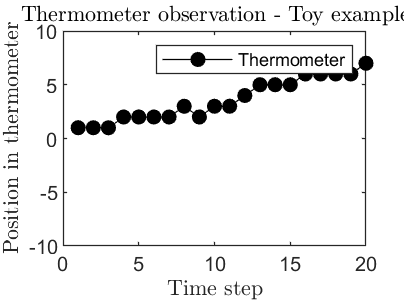

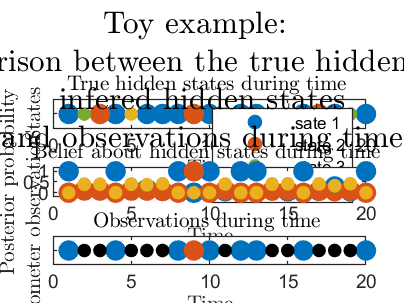

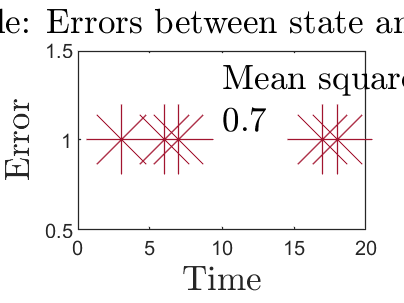

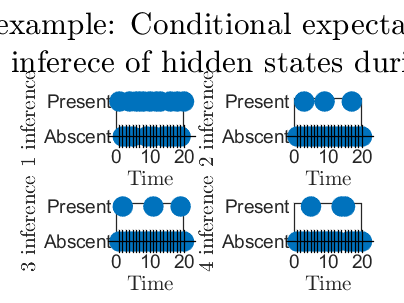

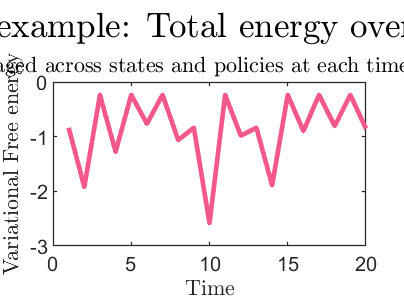

thesis_tutorial_observationsplots

### Actions

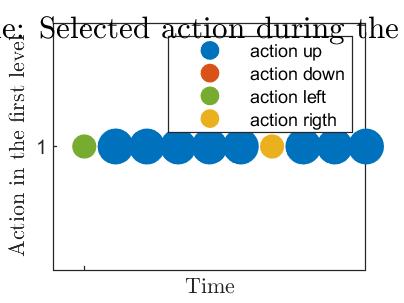

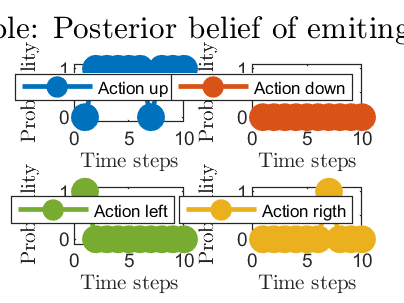

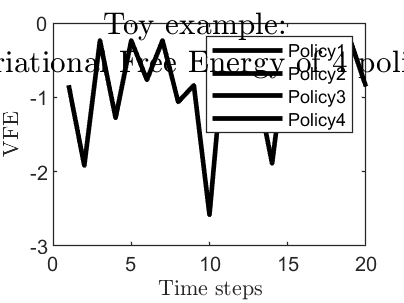

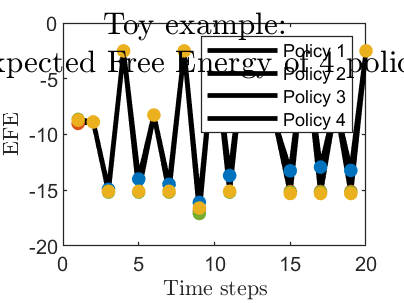

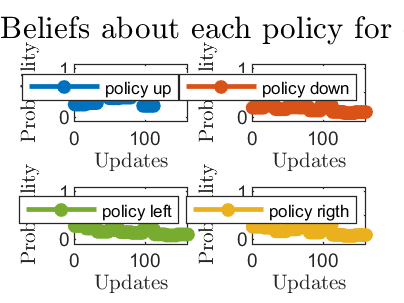

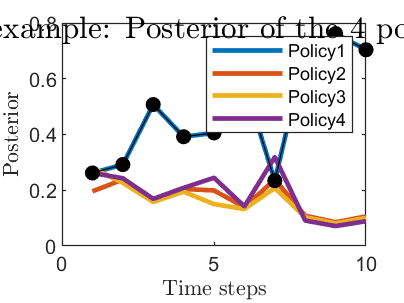

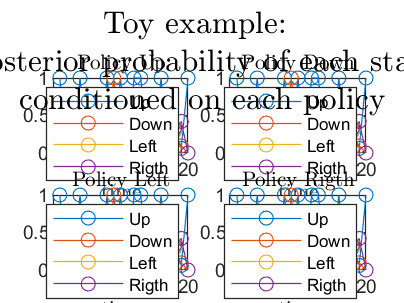

thesis_tutorial_actionandselection

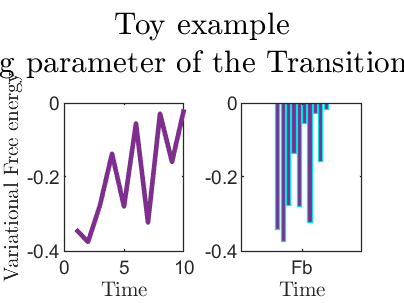

thesis_learning

## TEXTO summary results

#### sdk

#### jffghfh

Puede finalmente up-regulat de manera constante, pero toma mucho tiempo. 

Además, hay una selección indistinta de acción por sus consecuencias en el estado